# Ejercicio 5

### T2.5 Método de Newton-Raphson modificado para el cálculo de raíces múltiples

Grupo 8: 

Ana Robledano Abasolo, Alfredo Robledano Abasolo,  Melani Tatayo Culchas, Rubén Sierra Serrano.

28-02-2023

a) Escribe una función de Matlab que calcule la raíz de una función mediante el método de Newton-Raphson modificado de acuerdo con el algoritmo explicado anteriormente. Nombra a la función [xs,i] = newtonmod (f,xest,ermax)

- Véase newtonmod.m

b) Emplea la función anterior para calcular las raíces del polinomio: 


$$f\left(x\right)=x^3 -5x^2 +7x-3$$


Comenzando con xest = 0 y ermax = 1e-5

Haz lo mismo con la función newtonraphson de los ejercicios de clase. Compara los resultados.

- Desarrollo

Limpieza del workspace, y salidas.

clear, clc

Declaramos las variables de entrada.

syms x
f = x^3 - 5*x^2 + 7*x - 3;
xest = 0;
ermax = 1e-5;

Dibujamos la función para hacernos una idea del problema que estamos resolviendo.

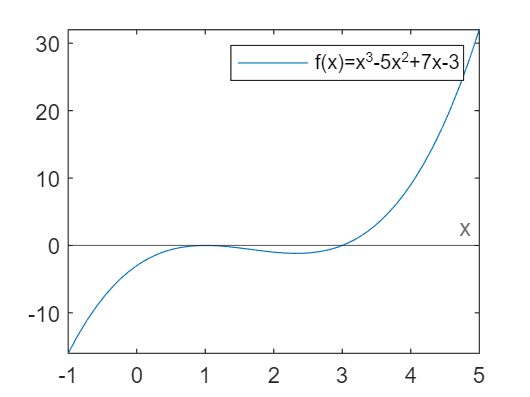

fplot(f, [-1, 5])
hold on
yline(0, '-', 'x')
legend({'f(x)=x^{3}-5x^{2}+7x-3'})
hold off

Calculamos la raíz próxima a cero con ambos métodos.

% Función Newton-Rapson modificada
[r_mod, i_mod] = newtonmod(f, xest, ermax);
% Función de clase
[r_clase, i_clase] = newton_rapson_tol_sol(f, xest, ermax);

Mostramos los resultados con 6 decimales.

fprintf("Raíz método clase: %.6f", r_clase);

Raíz método clase: 0.999994

fprintf("Se han requerido %d iteraciones.", i_clase);

Se han requerido 18 iteraciones.

fprintf("Raíz método modificado: %.6f", r_mod);

Raíz método modificado: 1.000000

fprintf("Se han requerido %d iteraciones.", i_mod);

Se han requerido 4 iteraciones.

Gráficamente:

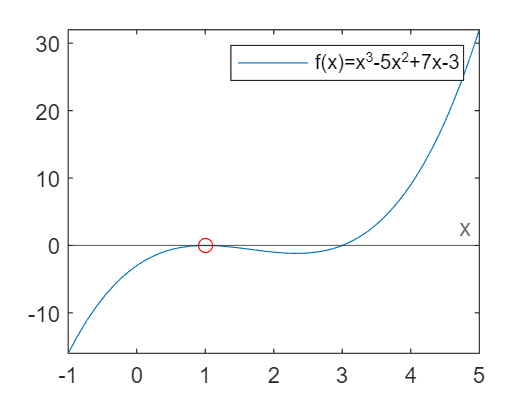

fplot(f, [-1, 5])
fx = matlabFunction(f);
hold on
plot(r_mod, fx(r_mod), 'ro')
yline(0, '-', 'x')
legend({'f(x)=x^{3}-5x^{2}+7x-3'})
hold off

Calculamos la diferencia relativa entre los dos métodos:

dif_r = abs((r_mod - r_clase) / r_clase) * 100;
fprintf("Las raíces calculadas difieren en un %.4f%%", dif_r);

Las raíces calculadas difieren en un 0.0006%

Conclusión:

El método modificado requiere de menos iteraciones y obtiene mayor precisión en el problema planteado.